# Machine Learning: Programming Exercise 2 

## Logistic Regression

In this exercise, you will implement logistic regression and apply it to two different datasets.

### Files needed for this exercise

- `ex2.mlx` - MATLAB Live Script that steps you through the exercise

- ex2data1.txt - Training set for the first half of the exercise

- ex2data2.txt - Training set for the second half of the exercise

- `submit.m` - Submission script that sends your solutions to our servers

- `mapFeature.m` - Function to generate polynomial features

- `plotDecisionBoundary.m` - Function to plot classifier's decision boundary

- *`plotData.m` - Function to plot 2D classification data

- *`sigmoid.m` - Sigmoid function

- *`costFunction.m` - Logistic regression cost function

- *`predict.m` - Logistic regression prediction function

- `*costFunctionReg.m` - Regularized logistic regression cost function

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex2' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Logistic Regression

In this part of the exercise, you will build a logistic regression model to predict whether a student gets admitted into a university. Suppose that you are the administrator of a university department and you want to determine each applicant's chance of admission based on their results on two exams. You have historical data from previous applicants that you can use as a training set for logistic regression. For each training example, you have the applicant's scores on two exams and the admissions decision.

    Your task is to build a classification model that estimates an applicant's probability of admission based the scores from those two exams. `ex2.mlx` will guide you through the exercise. To begin, run the code below to load the data into MATLAB.

% Load Data
% The first two columns contain the exam scores and the third column contains the label.
data = load('ex2data1.txt');
X = data(:, [1, 2]); y = data(:, 3);

### 1.1 Visualizing the data

Before starting to implement any learning algorithm, it is always good to visualize the data if possible. The code below will load the data and display it on a 2-dimensional plot by calling the function `plotData`. You will now complete the code in `plotData` so that it displays a figure like Figure 1, where the axes are the two exam scores, and the positive and negative examples are shown with different markers.

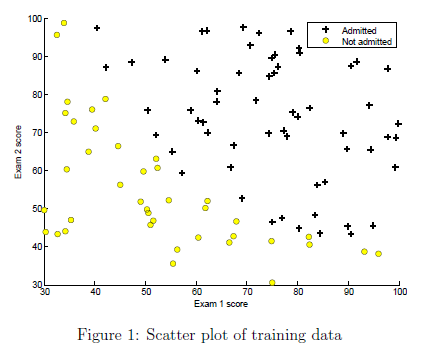

To help you get more familiar with plotting, we have left `plotData.m` empty so you can try to implement it yourself. However, this is an optional (ungraded) exercise. We also provide our implementation below so you can copy it or refer to it. If you choose to copy our example, make sure you learn what each of its commands is doing by consulting the MATLAB documentation.

Once you have added your own or the above code to `plotData.m`, run the code in this section to call the `plotData` function.

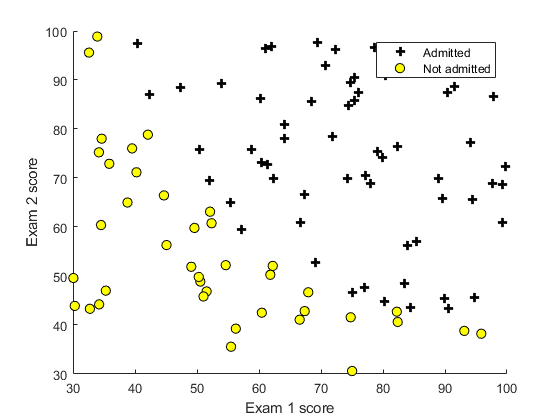

% Plot the data with + indicating (y = 1) examples and o indicating (y = 0) examples.
plotData(X, y);
 
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')

% Specified in plot order
legend('Admitted', 'Not admitted')

### 1.2 Implementation

#### 1.2.1 Warmup exercise: sigmoid function

Before you start with the actual cost function, recall that the logistic regression hypothesis is defined as:


$$ h_{\theta}(x) = g(\theta^Tx),$$


where function $g$ is the sigmoid function. The sigmoid function is defined as:


$$g(z) = \frac{1}{1+e^{-z}}$$


    Your first step is to implement this function in `sigmoid.m` so it can be called by the rest of your program. When you are finished, try testing a few values by calling `sigmoid(x)` in the code section below. For large positive values of `x`, the sigmoid should be close to 1, while for large negative values, the sigmoid should be close to 0. Evaluating `sigmoid(0)` should give you exactly 0.5. **Your code should also work with vectors and matrices**. For a matrix, your function should perform the sigmoid function on every element.

% Provide input values to the sigmoid function below and run to check your implementation
sigmoid(0)

g = 0.5000

ans = 0.5000

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.2.2 Cost function and gradient

Now you will implement the cost function and gradient for logistic regression. Complete the code in `costFunction.m` to return the cost and gradient. Recall that the cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


and the gradient of the cost is a vector of the same length as $\theta$ where the $j$th element (for $j = 0,\; 1,\ldots, n)$ is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}$$


Note that while this gradient looks identical to the linear regression gradient, the formula is actually different because linear and logistic regression have different definitions of $h_{\theta}(x)$. Once you are done, run the code sections below to set up your data and call your `costFunction` using the initial parameters of $\theta$. You should see that the cost is about 0.693 and gradients of about -0.1000,  -12.0092, and -11.2628

%  Setup the data matrix appropriately
[m, n] = size(X);

% Add intercept term to X
X = [ones(m, 1) X];   % [1 23 43]

% Initialize the fitting parameters
initial_theta = zeros(n + 1, 1);

% Compute and display the initial cost and gradient
[cost, grad] = costFunction(initial_theta, X, y);

g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


disp('Gradient at initial theta (zeros):'); disp(grad);

Gradient at initial theta (zeros):
   -0.1000  -12.0092  -11.2628



#### 1.2.3 Learning parameters using `fminunc`

In the previous assignment, you found the optimal parameters of a linear regression model by implementing gradent descent. You wrote a cost function and calculated its gradient, then took a gradient descent step accordingly. This time, instead of taking gradient descent steps, you will use a MATLAB built-in function called `fminunc`. 

    MATLAB's `fminunc` is an optimization solver that finds the minimum of an unconstrained* function. For logistic regression, you want to optimize the cost function $J(\theta)$ with parameters. Concretely, you are going to use `fminunc` to find the best parameters $\theta$ for the logistic regression cost function, given a fixed dataset (of $X$ and $y$ values). You will pass to `fminunc` the following inputs:

- The initial values of the parameters we are trying to optimize.

- A function that, when given the training set and a particular $\theta$ computes the logistic regression cost and gradient with respect to $\theta$ for the dataset $(X, y)$

**Constraints in optimization often refer to constraints on the parameters, for example, constraints that bound the possible values *$\theta$* can take (e.g. *$\theta<1$*). Logistic regression does not have such constraints since *$\theta$* is allowed to take any real value.*

We already have code written below to call `fminunc` with the correct arguments:

- We first define the options to be used with `fminunc`. Specically, we set the `GradObj` option to `on`, which tells `fminunc` that our function returns both the cost and the gradient. This allows `fminunc` to use the gradient when minimizing the function. 

- Furthermore, we set the `MaxIter` option to 400, so that `fminunc` will run for at most 400 steps before it terminates. 

- To specify the actual function we are minimizing, we use a 'short-hand' for specifying functions with: `@(t)(costFunction(t,X,y))`. This creates a function, with argument `t`, which calls your `costFunction`. This allows us to wrap the `costFunction` for use with `fminunc`.

- If you have completed the `costFunction` correctly, `fminunc` will converge on the right optimization parameters and return the final values of the cost and $\theta$. Notice that by using `fminunc`, you did not have to write any loops yourself, or set a learning rate like you did for gradient descent. This is all done by `fminunc`: you only needed to provide a function calculating the cost and the gradient.

- Once `fminunc` completes, the remaining code will call your `costFunction` function using the optimal parameters of $\theta$. You should see that the cost is about 0.203. This final $\theta$ value will then be used to plot the decision boundary on the training data, resulting in a figure similar to Figure 2. We also encourage you to look at the code in `plotDecisionBoundary.m` to see how to plot such a boundary using the $\theta$ values.

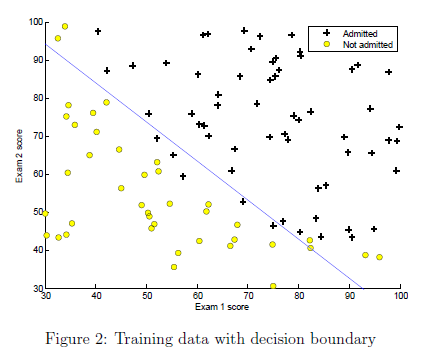

Run the code below and verify the results.

%  Set options for fminunc
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 400);

%  Run fminunc to obtain the optimal theta
%  This function will return theta and the cost 
[theta, cost] = fminunc(@(t)(costFunction(t, X, y)), initial_theta, options);

g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


g =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


g =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


g =     0.9667
    0.9032
    0.9629
    0.9880
    0.9908
    0.9552
    0.9913
    0.9761
    0.9929
    0.9804


g =     0.6546
    0.6044
    0.6498
    0.6978
    0.7084
    0.6412
    0.7108
    0.6690
    0.7186
    0.6776


g =     0.6451
    0.5984
    0.6407
    0.6874
    0.6988
    0.6336
    0.6995
    0.6619
    0.7080
    0.6706


g =     0.6383
    0.5949
    0.6345
    0.6811
    0.6944
    0.6295
    0.6925
    0.6600
    0.7025
    0.6694


g =     0.6225
    0.5879
    0.6204
    0.6688
    0.6889
    0.6221
    0.6778
    0.6616
    0.6933
    0.6736


g =     0.6040
    0.5814
    0.6044
    0.6575
    0.6885
    0.6164
    0.6630
    0.6707
    0.6875
    0.6870


g =     0.5934
    0.5796
    0.5959
    0.6544
    0.6951
    0.6165
    0.6574
    0.6840
    0.6898
    0.7039


g =     0.5944
    0.5815
    0.5972
    0.6580
    0.7009
    0.6197
    0.6607
    0.6906
    0.6949
    0.7114


g =     0.5964
    0.5826
    0.5991
    0.6600
    0.7024
    0.6210
    0.6630
    0.6915
    0.6968
    0.7121


g =     0.5973
    0.5830
    0.5999
    0.6608
    0.7028
    0.6215
    0.6639
    0.6915
    0.6974
    0.7120


g =     0.5995
    0.5840
    0.6019
    0.6626
    0.7038
    0.6226
    0.6660
    0.6915
    0.6988
    0.7117


g =     0.6026
    0.5853
    0.6046
    0.6650
    0.7050
    0.6240
    0.6689
    0.6915
    0.7007
    0.7113


g =     0.6077
    0.5874
    0.6092
    0.6693
    0.7072
    0.6265
    0.6740
    0.6915
    0.7040
    0.7105


g =     0.6158
    0.5906
    0.6163
    0.6760
    0.7106
    0.6302
    0.6821
    0.6913
    0.7093
    0.7093


g =     0.6286
    0.5950
    0.6276
    0.6869
    0.7164
    0.6359
    0.6952
    0.6909
    0.7182
    0.7072


g =     0.6483
    0.6006
    0.6449
    0.7044
    0.7260
    0.6443
    0.7163
    0.6899
    0.7327
    0.7036


g =     0.6778
    0.6053
    0.6704
    0.7321
    0.7420
    0.6553
    0.7497
    0.6873
    0.7567
    0.6971


g =     0.7186
    0.6019
    0.7051
    0.7742
    0.7689
    0.6670
    0.8000
    0.6808
    0.7953
    0.6852


g =     0.7679
    0.5695
    0.7452
    0.8326
    0.8119
    0.6711
    0.8671
    0.6652
    0.8523
    0.6636


g =     0.8121
    0.4566
    0.7760
    0.8989
    0.8729
    0.6449
    0.9352
    0.6319
    0.9203
    0.6283


g =     0.8231
    0.2225
    0.7643
    0.9509
    0.9363
    0.5420
    0.9778
    0.5805
    0.9717
    0.5933


g =     0.7580
    0.0480
    0.6552
    0.9761
    0.9753
    0.3454
    0.9928
    0.5432
    0.9923
    0.6068


g =     0.5599
    0.0054
    0.4082
    0.9863
    0.9916
    0.1456
    0.9972
    0.5301
    0.9980
    0.6729


g =     0.2971
    0.0005
    0.1731
    0.9906
    0.9968
    0.0474
    0.9986
    0.5143
    0.9994
    0.7362


g =     0.1584
    0.0001
    0.0806
    0.9922
    0.9982
    0.0200
    0.9991
    0.4881
    0.9997
    0.7631


g =     0.1046
    0.0000
    0.0499
    0.9928
    0.9987
    0.0118
    0.9993
    0.4604
    0.9998
    0.7671


g =     0.0889
    0.0000
    0.0415
    0.9928
    0.9987
    0.0096
    0.9993
    0.4410
    0.9998
    0.7605


g =     0.0855
    0.0000
    0.0397
    0.9926
    0.9987
    0.0091
    0.9993
    0.4291
    0.9998
    0.7519


g =     0.0860
    0.0000
    0.0401
    0.9921
    0.9986
    0.0092
    0.9992
    0.4183
    0.9998
    0.7402


g =     0.0889
    0.0000
    0.0419
    0.9915
    0.9984
    0.0097
    0.9991
    0.4141
    0.9998
    0.7322


g =     0.0918
    0.0000
    0.0438
    0.9909
    0.9983
    0.0104
    0.9991
    0.4158
    0.9997
    0.7298


g =     0.0926
    0.0000
    0.0446
    0.9905
    0.9982
    0.0108
    0.9990
    0.4202
    0.9997
    0.7319


g =     0.0918
    0.0000
    0.0443
    0.9904
    0.9982
    0.0109
    0.9990
    0.4230
    0.9997
    0.7346


g =     0.0912
    0.0000
    0.0440
    0.9904
    0.9982
    0.0108
    0.9990
    0.4234
    0.9997
    0.7354


g =     0.0910
    0.0000
    0.0439
    0.9904
    0.9982
    0.0108
    0.9990
    0.4233
    0.9997
    0.7354


g =     0.0910
    0.0000
    0.0439
    0.9904
    0.9982
    0.0108
    0.9990
    0.4232
    0.9997
    0.7354


g =     0.0910
    0.0000
    0.0439
    0.9904
    0.9982
    0.0108
    0.9990
    0.4232
    0.9997
    0.7354



Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>




% Print theta
fprintf('Cost at theta found by fminunc: %f\n', cost);

Cost at theta found by fminunc: 0.203498


disp('theta:');disp(theta);

theta:
  -25.1613
    0.2062
    0.2015



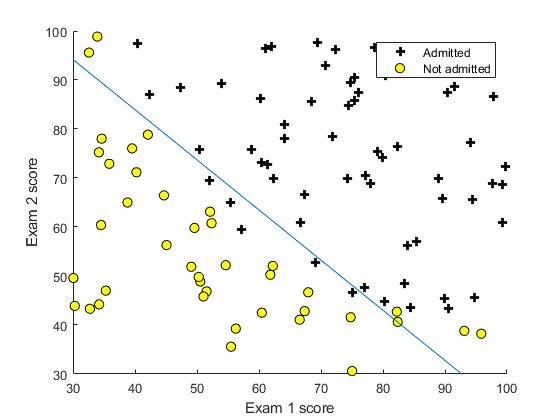


% Plot Boundary
plotDecisionBoundary(theta, X, y);
% Add some labels 
hold on;
% Labels and Legend
xlabel('Exam 1 score')
ylabel('Exam 2 score')
% Specified in plot order
legend('Admitted', 'Not admitted')
hold off;

#### 1.2.4 Evaluating logistic regression

After learning the parameters, you can use the model to predict whether a particular student will be admitted. For a student with an Exam 1 score of 45 and an Exam 2 score of 85, you should expect to see an admission probability of 0.776. Another way to evaluate the quality of the parameters we have found is to see how well the learned model predicts on our training set. In this part, your task is to complete the code in `predict.m`. The predict function will produce '1' or '0' predictions given a dataset and a learned parameter vector $\theta$.

    After you have completed the code in `predict.m`, the code below will proceed to report the training accuracy of your classifier by computing the percentage of examples it got correct. 

%  Predict probability for a student with score 45 on exam 1  and score 85 on exam 2 
prob = sigmoid([1 45 85] * theta);

g = 0.7763

fprintf('For a student with scores 45 and 85, we predict an admission probability of %f\n\n', prob);

For a student with scores 45 and 85, we predict an admission probability of 0.776291



% Compute accuracy on our training set
p = predict(theta, X);

g =     0.0910
    0.0000
    0.0439
    0.9904
    0.9982
    0.0108
    0.9990
    0.4232
    0.9997
    0.7354


fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 89.000000


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Regularized logistic regression

In this part of the exercise, you will implement regularized logistic regression to predict whether microchips from a fabrication plant passes quality assurance (QA). During QA, each microchip goes through various tests to ensure it is functioning correctly. Suppose you are the product manager of the factory and you have the test results for some microchips on two different tests. From these two tests, you would like to determine whether the microchips should be accepted or rejected. To help you make the decision, you have a dataset of test results on past microchips, from which you can build a logistic regression model.

### 2.1 Visualizing the data

Similar to the previous parts of this exercise, `plotData` is used in the code below to generate a figure like Figure 3, where the axes are the two test scores, and the positive ($y=1,$  accepted) and negative ($y=0,$ rejected) examples are shown with different markers. 

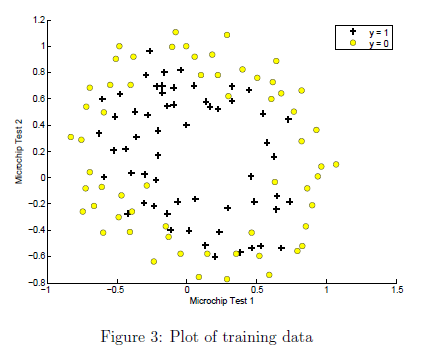

Run the code below and confirm you plot matches Figure 3.

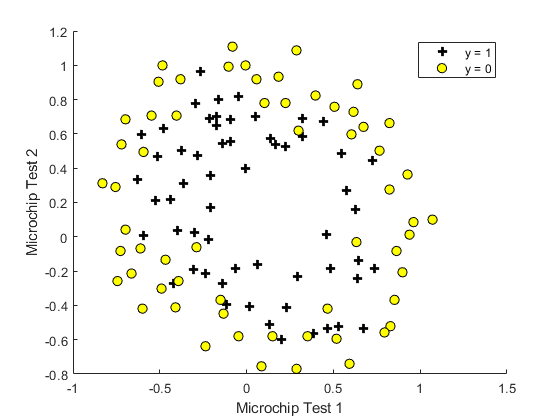

%  The first two columns contains the X values and the third column
%  contains the label (y).
data = load('ex2data2.txt');
X = data(:, [1, 2]); y = data(:, 3);

plotData(X, y);
% Put some labels 
hold on;
% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')
% Specified in plot order
legend('y = 1', 'y = 0')
hold off;

        Figure 3 shows that our dataset cannot be separated into positive and negative examples by a straight-line through the plot. Therefore, a straightforward application of logistic regression will not perform well on this dataset since logistic regression will only be able to find a linear decision boundary.

### 2.2 Feature mapping

One way to fit the data better is to create more features from each data point. In the provided function `mapFeature.m`, we will map the features into all polynomial terms of $x_1$ and $x_2$ up to the sixth power.


$$\text{mapFeature}\left(x\right)=\left\lbrack \begin{array}{c}
1\\
x_1 \\
x_2 \\
x_1^2 \\
x_1 x_2 \\
x_2^2 \\
x_1^3 \\
\vdots \text{ }\\
x_1 x_2^5 \\
x_2^6 
\end{array}\right\rbrack$$


    As a result of this mapping, our vector of two features (the scores on two QA tests) has been transformed into a 28-dimensional vector. A logistic regression classifier trained on this higher-dimension feature vector will have a more complex decision boundary and will appear nonlinear when drawn in our 2-dimensional plot. 

    Run the code below to map the features.

% Add Polynomial Features
% Note that mapFeature also adds a column of ones for us, so the intercept term is handled
X = mapFeature(X(:,1), X(:,2));

    While the feature mapping allows us to build a more expressive classifier, it also more susceptible to overfitting. In the next parts of the exercise, you will implement regularized logistic regression to fit the data and also see for yourself how regularization can help combat the overfitting problem.

### 2.3 Cost function and gradient

Now you will implement code to compute the cost function and gradient for regularized logistic regression. Complete the code in `costFunctionReg.m` to return the cost and gradient. Recall that the regularized cost function in logistic regression is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[
-y^{(i)} \log(h_{\theta}(x^{(i)}))-(1-y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2},$$


Note that you should not regularize the parameter $\theta_0$. In MATLAB, recall that indexing starts from 1, hence, you should not be regularizing the `theta(1)` parameter (which corresponds to $\theta_0$) in the code. The gradient of the cost function is a vector where the $j\mathrm{th}$ element is defined as follows:


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1,$$


Once you are done, run the code below to call your `costFunctionReg` function using the initial value of $\theta$ (initialized to all zeros). You should see that the cost is about 0.693.

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

% Set regularization parameter lambda to 1
lambda = 1;

% Compute and display initial cost and gradient for regularized logistic regression
[cost, grad] = costFunctionReg(initial_theta, X, y, lambda);

g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


fprintf('Cost at initial theta (zeros): %f\n', cost);

Cost at initial theta (zeros): 0.693147


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.3.1 Learning parameters using `fminunc`

Similar to the previous parts, the next step is to use `fminunc` to learn the optimal parameters. If you have completed the cost and gradient for regularized logistic regression (`costFunctionReg.m`) correctly, you should be able to run the code in the following sections to learn the parameters using `fminunc` for multiple values of $\lambda$.

### 2.4 Plotting the decision boundary

To help you visualize the model learned by this classifier, we have provided the function `plotDecisionBoundary.m` which plots the (nonlinear) decision boundary that separates the positive and negative examples. In `plotDecisionBoundary.m`, we plot the nonlinear decision boundary by computing the classifier's predictions on an evenly spaced grid and then drew a contour plot of where the predictions change from $y = 0$ to $y = 1$. After learning the parameters, the code in the next section will plot a decision boundary similar to Figure 4.

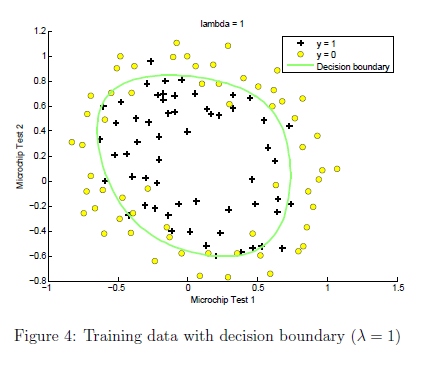

### 2.5 Optional (ungraded) exercises

In this part of the exercise, you will get to try out different regularization parameters for the dataset to understand how regularization prevents overfitting. Notice the changes in the decision boundary as you vary $\lambda$. With a small $\lambda$, you should find that the classifier gets almost every training example correct, but draws a very complicated boundary, thus overfitting the data (Figure 5). 

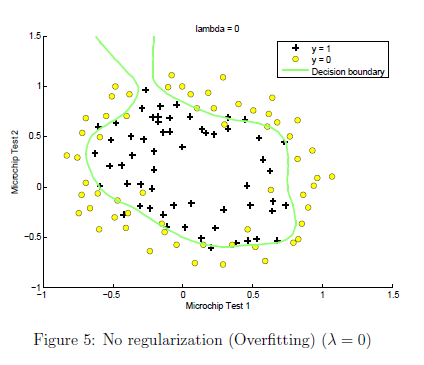

    This is not a good decision boundary: for example, it predicts that a point at $x = (0.25, 1.5)$ is accepted $(y = 1)$, which seems to be an incorrect decision given the training set. With a larger $\lambda$, you should see a plot that shows an simpler decision boundary which still separates the positives and negatives fairly well. However, if $\lambda$ is set to too high a value, you will not get a good fit and the decision boundary will not follow the data so well, thus underfitting the data (Figure 6).

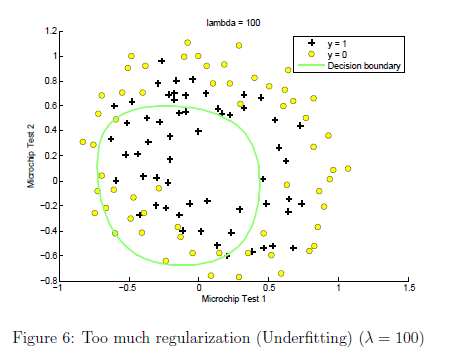

Use the control below to try the following values of $\lambda$: 0, 1, 10, 100. 

- How does the decision boundary change when you vary $\lambda$? 

- How does the training set accuracy vary?

% Initialize fitting parameters
initial_theta = zeros(size(X, 2), 1);

lambda = 0;
% Set Options
options = optimoptions(@fminunc,'Algorithm','Quasi-Newton','GradObj', 'on', 'MaxIter', 1000);

% Optimize
[theta, J, exit_flag] = fminunc(@(t)(costFunctionReg(t, X, y, lambda)), initial_theta, options);

g =     0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000
    0.5000


g =     0.4836
    0.4873
    0.4884
    0.4873
    0.4837
    0.4833
    0.4869
    0.4882
    0.4847
    0.4803


g =     0.5422
    0.5519
    0.5532
    0.5449
    0.5277
    0.5258
    0.5427
    0.5499
    0.5454
    0.5325


g =     0.6035
    0.6119
    0.6073
    0.5839
    0.5453
    0.5412
    0.5788
    0.5965
    0.6069
    0.5917


g =     0.6637
    0.6646
    0.6482
    0.5988
    0.5252
    0.5175
    0.5887
    0.6242
    0.6659
    0.6532


g =     0.6995
    0.6907
    0.6618
    0.5862
    0.4787
    0.4678
    0.5712
    0.6245
    0.6998
    0.6925


g =     0.7098
    0.6938
    0.6566
    0.5649
    0.4394
    0.4270
    0.5471
    0.6109
    0.7086
    0.7062


g =     0.7084
    0.6878
    0.6462
    0.5474
    0.4163
    0.4036
    0.5286
    0.5966
    0.7061
    0.7074


g =     0.7042
    0.6824
    0.6403
    0.5416
    0.4120
    0.3995
    0.5229
    0.5906
    0.7016
    0.7042


g =     0.7020
    0.6804
    0.6390
    0.5421
    0.4146
    0.4023
    0.5238
    0.5902
    0.6993
    0.7019


g =     0.6998
    0.6792
    0.6390
    0.5447
    0.4196
    0.4074
    0.5267
    0.5916
    0.6973
    0.6995


g =     0.6968
    0.6782
    0.6405
    0.5500
    0.4278
    0.4158
    0.5327
    0.5952
    0.6948
    0.6959


g =     0.6922
    0.6781
    0.6452
    0.5614
    0.4421
    0.4301
    0.5448
    0.6038
    0.6910
    0.6894


g =     0.6856
    0.6806
    0.6563
    0.5823
    0.4632
    0.4506
    0.5665
    0.6211
    0.6865
    0.6787


g =     0.6793
    0.6886
    0.6761
    0.6120
    0.4849
    0.4704
    0.5964
    0.6480
    0.6835
    0.6653


g =     0.6782
    0.7005
    0.6968
    0.6356
    0.4895
    0.4720
    0.6188
    0.6724
    0.6856
    0.6570


g =     0.6817
    0.7085
    0.7062
    0.6395
    0.4725
    0.4524
    0.6205
    0.6802
    0.6903
    0.6575


g =     0.6842
    0.7104
    0.7068
    0.6346
    0.4570
    0.4359
    0.6143
    0.6784
    0.6927
    0.6599


g =     0.6847
    0.7104
    0.7061
    0.6321
    0.4516
    0.4302
    0.6114
    0.6768
    0.6931
    0.6606


g =     0.6849
    0.7100
    0.7048
    0.6286
    0.4445
    0.4229
    0.6074
    0.6745
    0.6932
    0.6612


g =     0.6843
    0.7085
    0.7024
    0.6234
    0.4342
    0.4121
    0.6015
    0.6709
    0.6924
    0.6612


g =     0.6812
    0.7049
    0.6986
    0.6171
    0.4206
    0.3978
    0.5943
    0.6663
    0.6890
    0.6589


g =     0.6714
    0.6970
    0.6936
    0.6130
    0.4074
    0.3834
    0.5896
    0.6627
    0.6794
    0.6501


g =     0.6488
    0.6821
    0.6893
    0.6204
    0.4067
    0.3806
    0.5975
    0.6661
    0.6578
    0.6280


g =     0.6137
    0.6626
    0.6902
    0.6481
    0.4364
    0.4080
    0.6281
    0.6831
    0.6250
    0.5922


g =     0.5872
    0.6491
    0.6945
    0.6795
    0.4862
    0.4574
    0.6636
    0.7024
    0.6003
    0.5652


g =     0.5802
    0.6444
    0.6953
    0.6927
    0.5200
    0.4929
    0.6795
    0.7092
    0.5935
    0.5591


g =     0.5823
    0.6437
    0.6929
    0.6920
    0.5298
    0.5041
    0.6797
    0.7071
    0.5949
    0.5622


g =     0.5841
    0.6438
    0.6913
    0.6890
    0.5285
    0.5032
    0.6767
    0.7045
    0.5964
    0.5643


g =     0.5844
    0.6438
    0.6908
    0.6878
    0.5271
    0.5019
    0.6755
    0.7036
    0.5967
    0.5646


g =     0.5843
    0.6438
    0.6909
    0.6879
    0.5270
    0.5018
    0.6755
    0.7037
    0.5966
    0.5643


g =     0.5841
    0.6439
    0.6912
    0.6884
    0.5274
    0.5021
    0.6760
    0.7041
    0.5964
    0.5640


g =     0.5840
    0.6440
    0.6915
    0.6888
    0.5277
    0.5025
    0.6764
    0.7045
    0.5964
    0.5638


g =     0.5839
    0.6443
    0.6920
    0.6895
    0.5283
    0.5030
    0.6771
    0.7051
    0.5964
    0.5636


g =     0.5837
    0.6446
    0.6927
    0.6905
    0.5292
    0.5039
    0.6781
    0.7060
    0.5964
    0.5632


g =     0.5836
    0.6453
    0.6939
    0.6921
    0.5307
    0.5052
    0.6798
    0.7075
    0.5964
    0.5626


g =     0.5834
    0.6465
    0.6960
    0.6947
    0.5329
    0.5073
    0.6824
    0.7099
    0.5965
    0.5617


g =     0.5831
    0.6486
    0.6994
    0.6987
    0.5361
    0.5103
    0.6864
    0.7138
    0.5968
    0.5602


g =     0.5829
    0.6525
    0.7051
    0.7044
    0.5401
    0.5140
    0.6920
    0.7198
    0.5977
    0.5577


g =     0.5833
    0.6596
    0.7141
    0.7117
    0.5437
    0.5173
    0.6988
    0.7282
    0.6000
    0.5536


g =     0.5851
    0.6714
    0.7267
    0.7176
    0.5422
    0.5155
    0.7033
    0.7376
    0.6049
    0.5480


g =     0.5895
    0.6862
    0.7386
    0.7145
    0.5267
    0.5003
    0.6975
    0.7421
    0.6130
    0.5425


g =     0.5943
    0.6943
    0.7401
    0.6975
    0.4970
    0.4714
    0.6773
    0.7342
    0.6197
    0.5411


g =     0.5949
    0.6909
    0.7321
    0.6808
    0.4755
    0.4505
    0.6591
    0.7216
    0.6195
    0.5431


g =     0.5940
    0.6862
    0.7261
    0.6751
    0.4725
    0.4478
    0.6536
    0.7156
    0.6175
    0.5449


g =     0.5938
    0.6853
    0.7253
    0.6748
    0.4732
    0.4485
    0.6535
    0.7149
    0.6171
    0.5453


g =     0.5938
    0.6853
    0.7252
    0.6748
    0.4733
    0.4486
    0.6535
    0.7149
    0.6171
    0.5454


g =     0.5939
    0.6853
    0.7252
    0.6748
    0.4733
    0.4486
    0.6535
    0.7149
    0.6171
    0.5454


g =     0.5939
    0.6853
    0.7252
    0.6748
    0.4733
    0.4486
    0.6535
    0.7149
    0.6172
    0.5454


g =     0.5939
    0.6853
    0.7252
    0.6747
    0.4732
    0.4485
    0.6534
    0.7148
    0.6172
    0.5455


g =     0.5940
    0.6853
    0.7251
    0.6747
    0.4731
    0.4484
    0.6533
    0.7148
    0.6173
    0.5456


g =     0.5941
    0.6854
    0.7251
    0.6745
    0.4729
    0.4483
    0.6532
    0.7147
    0.6174
    0.5457


g =     0.5943
    0.6855
    0.7250
    0.6743
    0.4727
    0.4480
    0.6529
    0.7145
    0.6176
    0.5459


g =     0.5947
    0.6856
    0.7249
    0.6739
    0.4722
    0.4476
    0.6525
    0.7142
    0.6179
    0.5462


g =     0.5953
    0.6859
    0.7247
    0.6732
    0.4716
    0.4470
    0.6517
    0.7137
    0.6185
    0.5468


g =     0.5966
    0.6863
    0.7242
    0.6718
    0.4707
    0.4462
    0.6504
    0.7126
    0.6196
    0.5479


g =     0.5990
    0.6873
    0.7232
    0.6693
    0.4694
    0.4452
    0.6479
    0.7105
    0.6219
    0.5500


g =     0.6038
    0.6891
    0.7212
    0.6646
    0.4684
    0.4446
    0.6433
    0.7064
    0.6264
    0.5541


g =     0.6127
    0.6924
    0.7172
    0.6563
    0.4691
    0.4465
    0.6355
    0.6985
    0.6348
    0.5615


g =     0.6254
    0.6968
    0.7107
    0.6456
    0.4755
    0.4546
    0.6263
    0.6871
    0.6467
    0.5722


g =     0.6350
    0.6993
    0.7049
    0.6398
    0.4881
    0.4688
    0.6225
    0.6785
    0.6555
    0.5805


g =     0.6365
    0.6990
    0.7030
    0.6410
    0.4980
    0.4791
    0.6250
    0.6773
    0.6568
    0.5817


g =     0.6348
    0.6983
    0.7034
    0.6431
    0.5005
    0.4815
    0.6273
    0.6786
    0.6552
    0.5798


g =     0.6339
    0.6983
    0.7040
    0.6435
    0.5001
    0.4811
    0.6276
    0.6793
    0.6545
    0.5788


g =     0.6337
    0.6983
    0.7042
    0.6436
    0.4997
    0.4806
    0.6275
    0.6795
    0.6544
    0.5786


g =     0.6337
    0.6984
    0.7042
    0.6435
    0.4995
    0.4805
    0.6275
    0.6795
    0.6544
    0.5786


g =     0.6337
    0.6984
    0.7042
    0.6435
    0.4995
    0.4805
    0.6275
    0.6795
    0.6544
    0.5786



Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<stopping criteria details>



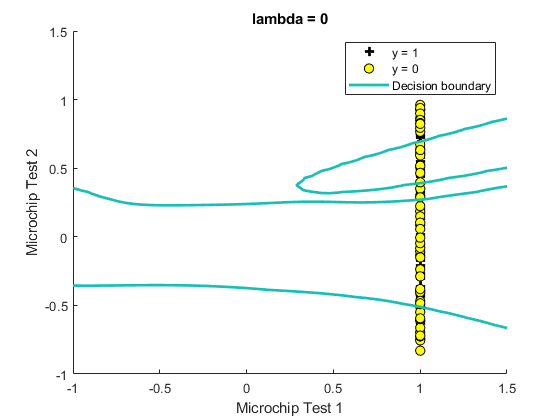

% Plot Boundary
plotDecisionBoundary(theta, X, y);
hold on;
title(sprintf('lambda = %g', lambda))

% Labels and Legend
xlabel('Microchip Test 1')
ylabel('Microchip Test 2')

legend('y = 1', 'y = 0', 'Decision boundary')
hold off;


% Compute accuracy on our training set
p = predict(theta, X);

g =     0.6337
    0.6984
    0.7042
    0.6435
    0.4995
    0.4805
    0.6275
    0.6795
    0.6544
    0.5786



fprintf('Train Accuracy: %f\n', mean(double(p == y)) * 100);

Train Accuracy: 63.559322


*You do not need to submit any solutions for these optional (ungraded) exercises.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the `submit` function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

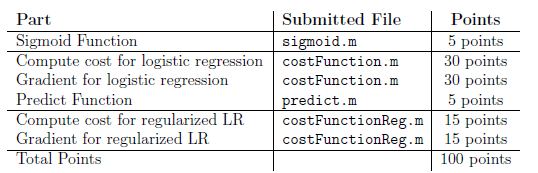

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.